% loads data sets

set1 = load('../dat/1_9kb_final/nucleus_struct.mat');
set2 = load('../dat/2_65kb_final/nucleus_struct.mat');
set3 = load('../dat/3_4kb_final/nucleus_struct.mat');

% Pick out a subset of data
nc = 14;
nucleus_struct = set3.nucleus_struct;

subset = nucleus_struct([nucleus_struct.ncStart] == nc);
display(median(diff([subset.time_interp])));

     7



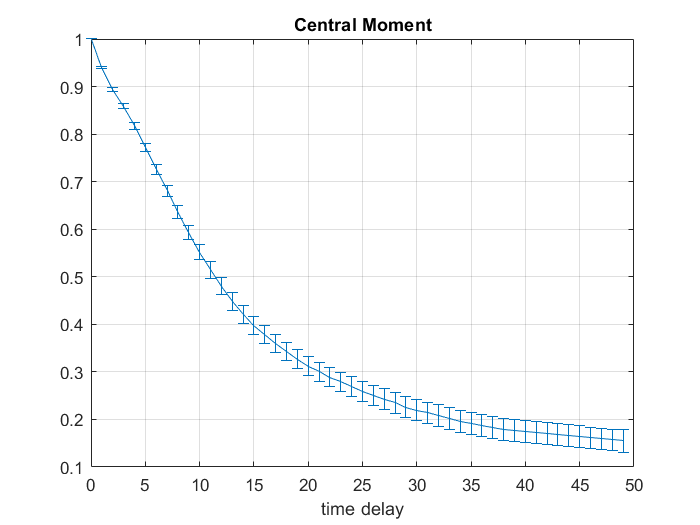

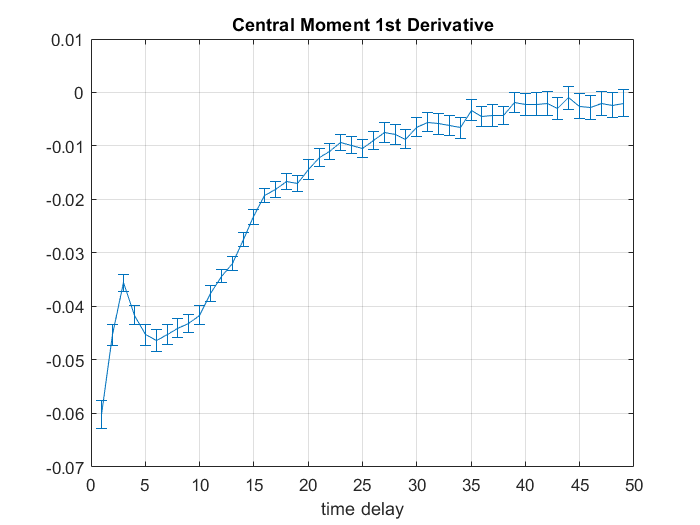

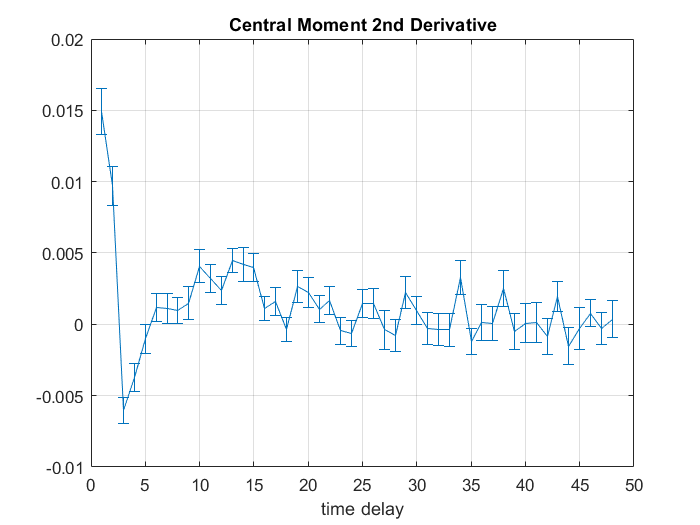

% Run autocorrelation on subset of data
sum_all = zeros(1, 600);
idxes = zeros(1, 600);
traces = {};
min_trace = 100;
idx = 1;
field = 'fluo3D_interp';
for s = subset
    if sum(isnan(s.(field))) == 0 && s.inference_flag
        marks = find(s.(field) < 10);
        marks = [1 marks length(s.(field))];
        for i = 2:length(marks)
            if marks(i) - marks(i - 1) > min_trace
                first = marks(i-1) + 15;
                last = marks(i) - 15;
                traces{idx} = s.(field)(first:1:last);
                len = length(traces{idx});
                sum_all(1:len) = sum_all(1:len) + traces{idx};
                idxes(1:len) = idxes(1:len) + 1;
                idx = idx + 1;

            end
        end
    end
end

gen_auto_cor(traces, true, true, true, true, 50, 0);

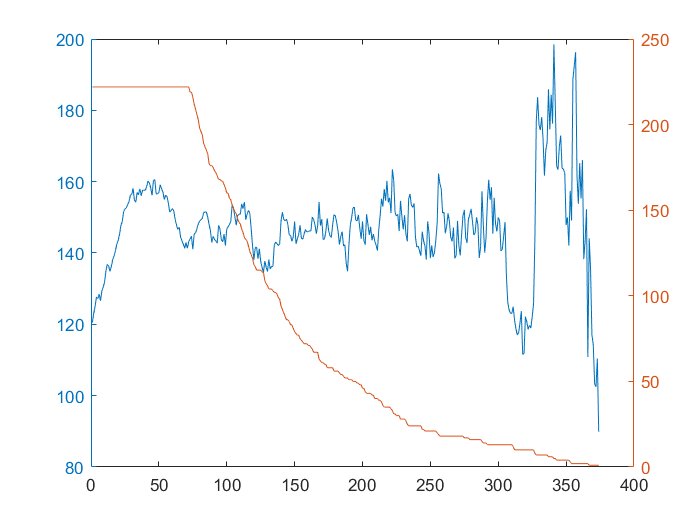


last_idx = find(idxes > 0, 1, 'last' );
sum_all = sum_all(1:last_idx) ./ idxes(1:last_idx);
figure();
yyaxis left
plot(sum_all)
yyaxis right
plot(idxes(1:last_idx))

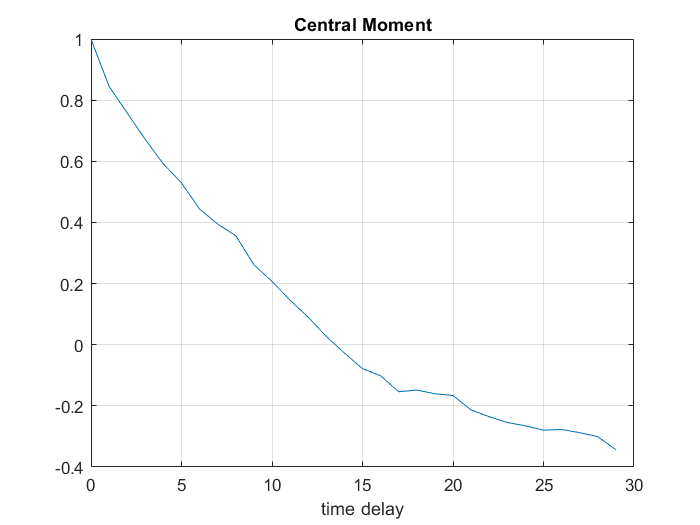

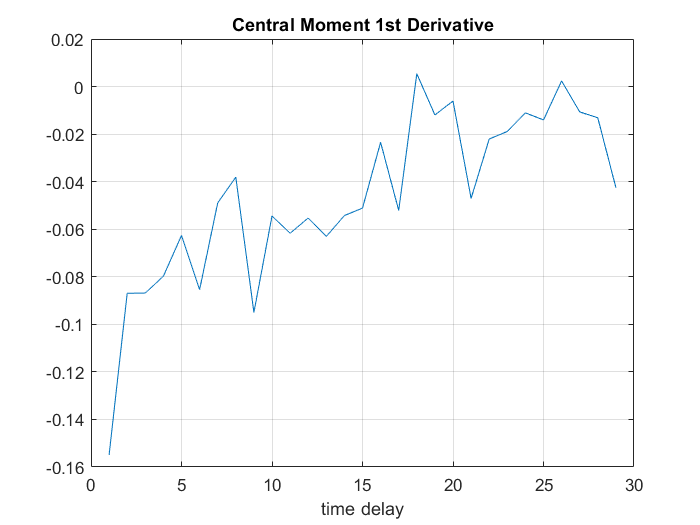

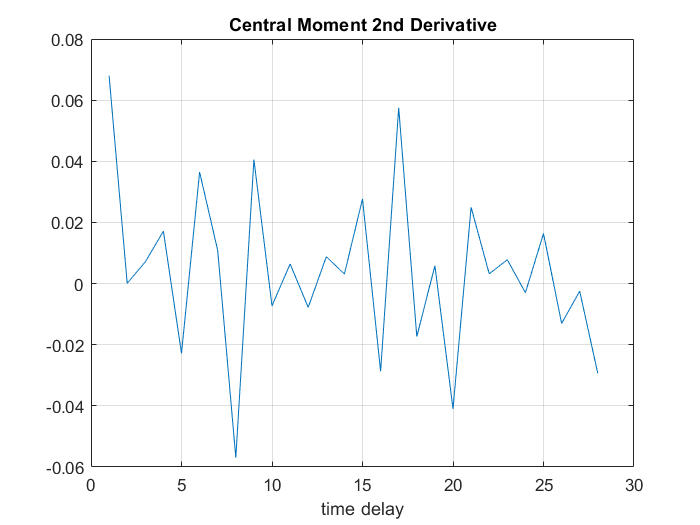

gen_auto_cor({sum_all}, true, true, true, false, 30, 0);

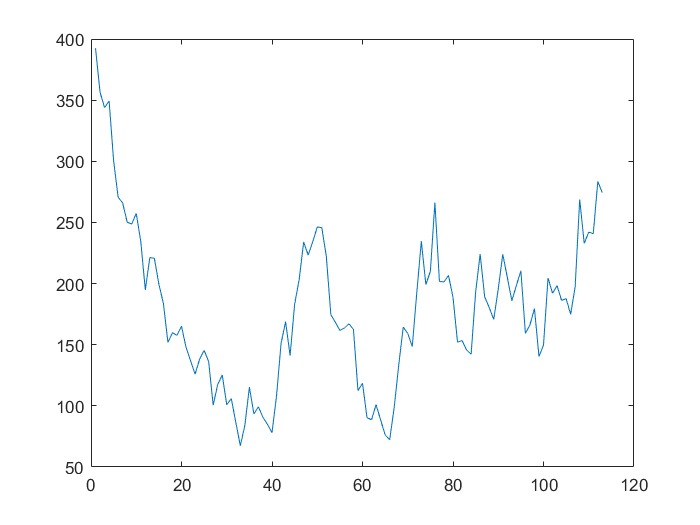

% show traces
i = 11;
figure();
plot(traces{i});

%gen_auto_cor({traces{i}}, true, true, true, false, 30, 0);

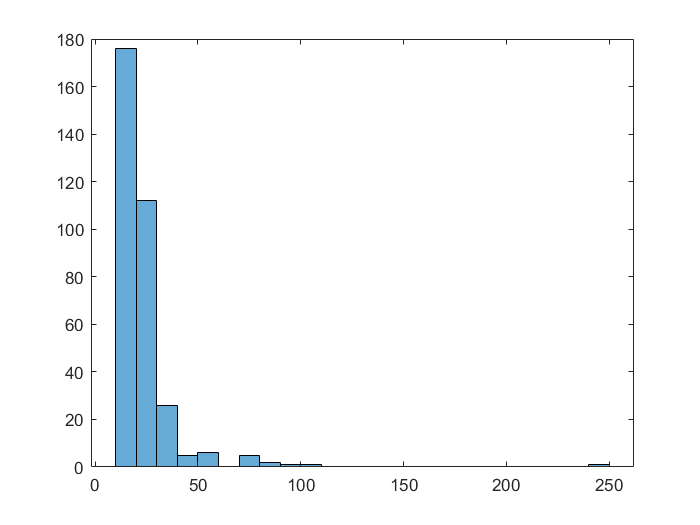

% Find distribution of first points

dist = [];
dist2 = [];
dist3 = [];
for t = 1:length(traces)
    trace = traces{t};
    dist = [dist trace(2)];
    dist2 = [dist2 trace];
    dist3 = [dist3 trace(2:end) - trace(1:end-1)];
end
figure();
histogram(dist);

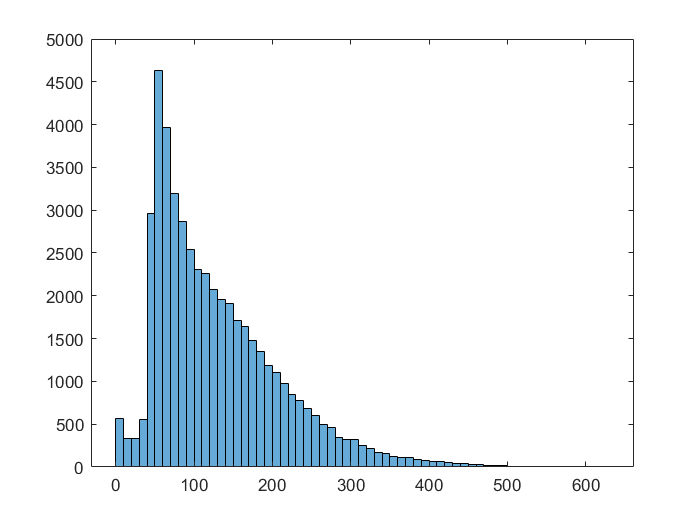

figure();
histogram(dist2);

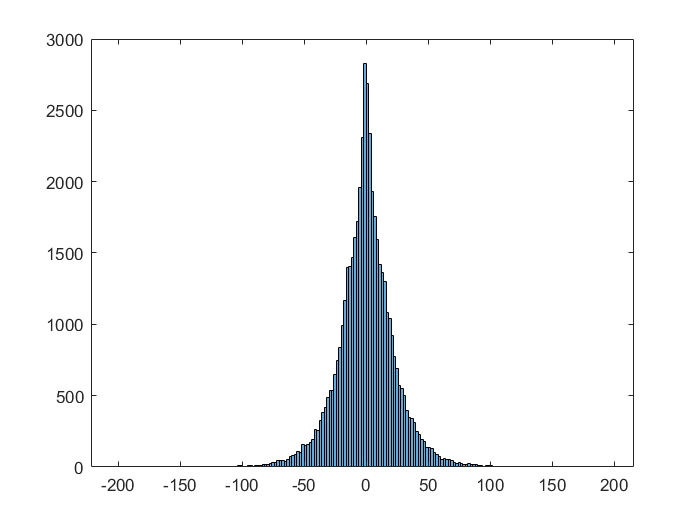

figure();
histogram(dist3);

avg = mean(dist2)

avg = 129.9266

std(dist2)

ans = 81.1987